# **1D Heat equation** - Explore the `PDE toolbox`

Recall a summary of our specific **Boundary value problem** problem:

-    $\frac{\partial U}{\partial t}\;\;\;=\;\;\;\;\alpha \;\ldotp \;\frac{\partial^2 }{\partial x^2 }U$      for   $\left(0<x<1\right)$   and    $\left(t\;>\;0\right)$

- $U\left(x,t\right)$    :     Temperature     $\left\lbrack \circ K\;\right\rbrack$

- $x$             :     a  position          $\left\lbrack m\;\;\right\rbrack$

- $t$             :      a  time               $\left\lbrack \sec \;\;\right\rbrack$

- $\alpha$            :  Thermal diffusivity  $\left\lbrack \frac{m^2 }{\sec }\right\rbrack$    ***ATTENTION***:   we will use $\alpha =1$

- BCs:    $\begin{array}{l}
U\left(0,t\right)\;=0\\
U_X \left(1,t\right)=1
\end{array}$    for $\left(t\;>\;0\right)$

- ICs:    $U\left(x,0\right)=f\left(x\right)$    where   $f\left(x\right)\;\;=\;\;x\;\;\;+\;\;\;A\ldotp \sin \left(\frac{\pi \ldotp x}{2}\right)\;\;\;+\;\;\;B\ldotp \sin \left(\frac{P\ldotp \pi \ldotp x}{2}\right)$    where    $\begin{array}{l}
A=2\ldotp 2\\
B=0\ldotp 7\\
P=3\;\;\;
\end{array}$

## **Create a Transient Thermal model**

thermalmodel = createpde('thermal','transient');

Define the geometry of your system:

- For a rectangle, the first row contains 3, and the second row contains 4. 

- The next four rows contain the x-coordinates of the starting points of the edges, and the four rows after that contain the y-coordinates of the starting points of the edges.

bh_GEOM.rect_width  = 1;
bh_GEOM.rect_height = 0.1;

gdm = [3 4   0      bh_GEOM.rect_width   bh_GEOM.rect_width      0 ...
             0      0                    bh_GEOM.rect_height     bh_GEOM.rect_height]';
g = decsg(gdm, 'S1', ('S1')' );

geometryFromEdges(thermalmodel,g);

## Visualize the geometry

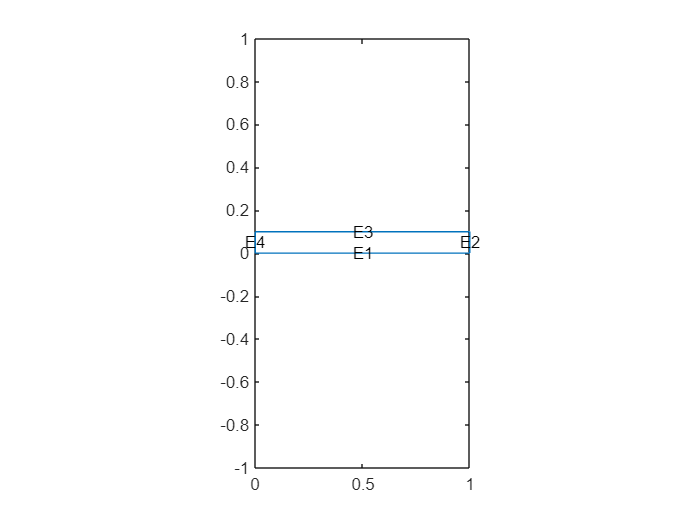

figure;
    pdegplot(thermalmodel,'EdgeLabels','on')
        ylim([-1,1])
        axis equal

## Specify Thermal Properties of the Material

Specify the thermal conductivity, mass density, and specific heat of the material.

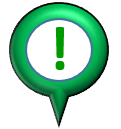RECALL**:    **$\alpha \;\;=\;1\;=\;\frac{k}{\rho \;\ldotp c_P }\;\;\;\;\left\lbrack \frac{m^2 }{\sec }\right\rbrack$     where:     $k\;\;\left\lbrack \frac{W}{m\ldotp K}\right\rbrack$     and     $\rho \;\;\left\lbrack \frac{\textrm{kg}}{m^3 }\right\rbrack$     and     $c_P \;\;\left\lbrack \frac{J}{\textrm{kg}\ldotp K}\right\rbrack$    

thermalProperties(thermalmodel, 'ThermalConductivity',1,...
                                'MassDensity',        1,...
                                'SpecificHeat',       1);

## Apply Boundary Conditions

The following documentation gives some background on the types of equations that the PDE toolbox can solve - this is useful for understanding how to configure the system boundary conditions:

- 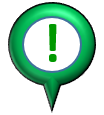 Equations You can solve Using the PDE Toolbox - see [`here`](matlab:  web(fullfile(docroot, 'pde/ug/equations-you-can-solve.html')))

- Specify Boundary Conditions - see [`here`](matlab:  web(fullfile(docroot, 'pde/ug/steps-to-specify-a-boundary-conditions-object.html')))

NOTE:   The toolbox uses the default insulating boundary condition for boundaries not explicitly configured.  Our boundary conditions are:

- BCs:    $\begin{array}{l}
U\left(0,t\right)\;=0\\
U_X \left(1,t\right)=1
\end{array}$    for $\left(t\;>\;0\right)$

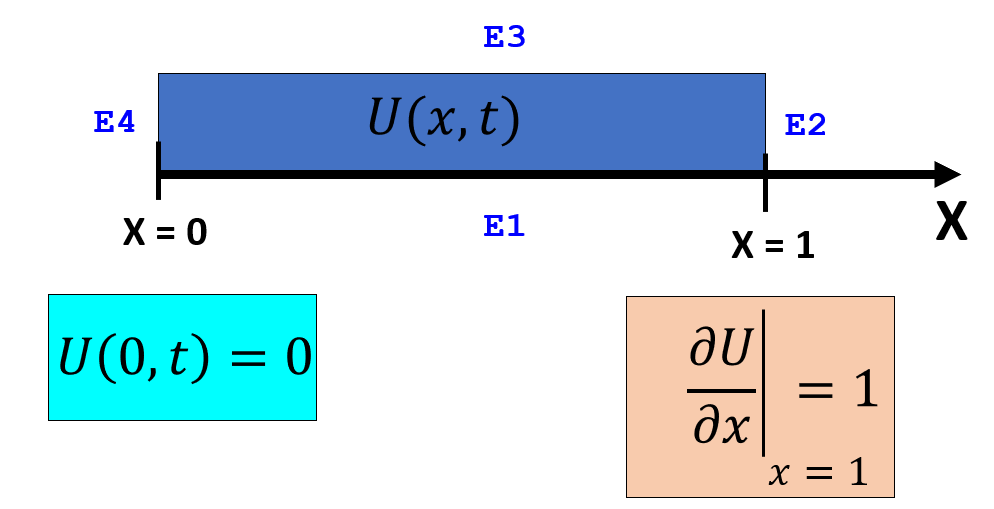

### Boundary Condition #1:

thermalBC(thermalmodel,'Edge',4,'Temperature',0);

### Boundary Condition #2:

Our 2nd boundary condition is assocaited with a constant heat flux at the right hand edge.  Recall that heat flux is defined as $\vec{\phi_q \;} =-k\ldotp \nabla T$.  

**ATTENTION:**   The [`thermalBC()`](matlab:  web(fullfile(docroot, 'pde/ug/pde.thermalmodel.thermalbc.html#bvinu67-1'))) function allows us to define the heatflux .... but the [`CONVENTION used`](matlab:  web(fullfile(docroot, 'pde/ug/heat-equation-for-metal-block-with-cavity.html'))) is that heat flowing INTO the solid edge is POSITIVE, therefore for our problem we have:

- 
$$\vec{\phi_q \;} =\;k\ldotp \frac{\partial U}{\partial x}=1\ldotp 1=1$$


thermalBC(thermalmodel,'Edge',2,'HeatFlux',1);

## Set Initial Conditions

Set an initial value for the temperature.

- ICs:    $U\left(x,0\right)=f\left(x\right)$    where   $f\left(x\right)\;\;=\;\;x\;\;\;+\;\;\;A\ldotp \sin \left(\frac{\pi \ldotp x}{2}\right)\;\;\;+\;\;\;B\ldotp \sin \left(\frac{P\ldotp \pi \ldotp x}{2}\right)$    where    $\begin{array}{l}
A=2\ldotp 2\\
B=0\ldotp 7\\
P=3\;\;\;
\end{array}$

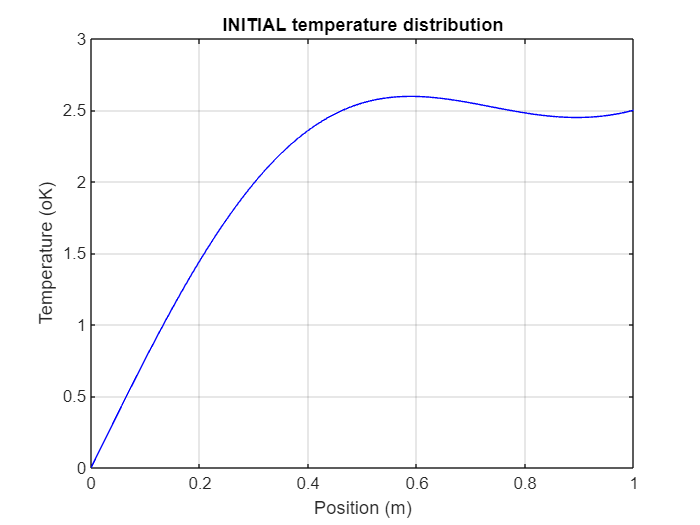

[A,B,P] = LOC_get_ABP();
T0      = @(location) location.x + A*sin(pi*location.x/2)  + B*sin(P*pi*location.x/2);

thermalIC(thermalmodel, T0);

LOC_plot_IC(T0, [0, 1])

## Generate Mesh

Create and plot a mesh.

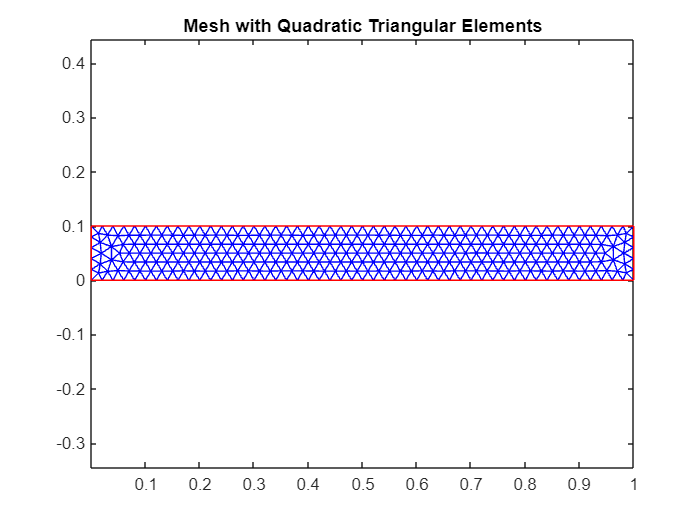

generateMesh(thermalmodel, "Hmax", 0.02);

figure
    pdemesh(thermalmodel)
        title('Mesh with Quadratic Triangular Elements')

## Specify Solution Times

tlist = 0 : 0.001 : 0.084;  %0.2;

## Calculate Solution

Use the `solve` function to calculate the solution.

thermalresults = solve(thermalmodel,tlist)

thermalresults =   TransientThermalResults with properties:

      Temperature: [1311×85 double]
    SolutionTimes: [0 1.0000e-03 0.0020 0.0030 0.0040 0.0050 0.0060 0.0070 0.0080 0.0090 0.0100 0.0110 0.0120 0.0130 0.0140 0.0150 0.0160 0.0170 0.0180 0.0190 0.0200 0.0210 0.0220 0.0230 0.0240 0.0250 0.0260 0.0270 0.0280 0.0290 0.0300 0.0310 0.0320 … ]
       XGradients: [1311×85 double]
       YGradients: [1311×85 double]
       ZGradients: []
             Mesh: [1×1 FEMesh]


Ans we can also compute the heat flux:

- Let's compute the heat flux at the RIGHT hand boundary (ie x = bh_GEOM.rect_width)  at   the first and last time samples

tmp_xq = bh_GEOM.rect_width* ones(1,10);
tmp_yq = linspace(0,bh_GEOM.rect_height,10);

[qx_at_t0,   ~  ] = evaluateHeatFlux(thermalresults, tmp_xq,  tmp_yq,  1);
[qx_at_tend,   ~] = evaluateHeatFlux(thermalresults, tmp_xq,  tmp_yq,  length(thermalresults.SolutionTimes));

So what is the heat flux at the RIGHT edge boundary ? 

qx_at_t0'

ans =    -0.9999   -1.0000   -1.0000   -0.9999   -0.9999   -0.9999   -0.9999   -1.0000   -1.0000   -0.9999


qx_at_tend'

ans =    -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000


## Visualize the results:

Plot the solution with isothermal lines by using a contour plot.

T = thermalresults.Temperature;

Pick an instant in time 

kk_norm = 0;
t_kk    = round( kk_norm*length(tlist)  );
if(0==t_kk) t_kk=1; end

And then plot the temperature along the length of the rod

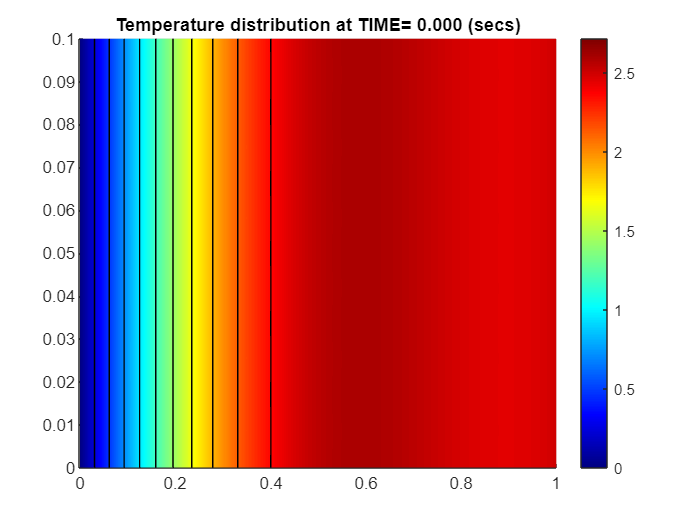

figure;
    pdeplot(thermalmodel,'XYData',T(:,t_kk),'Contour','on','ColorMap','jet');
        set(gca, "CLim",[min(thermalresults.Temperature(:)),  max(thermalresults.Temperature(:))]);
        grid on
        title("Temperature distribution at TIME= " + num2str(tlist(t_kk), "%.3f") + " (secs)" )

And we can also visualize the heat flux at that instant in time:

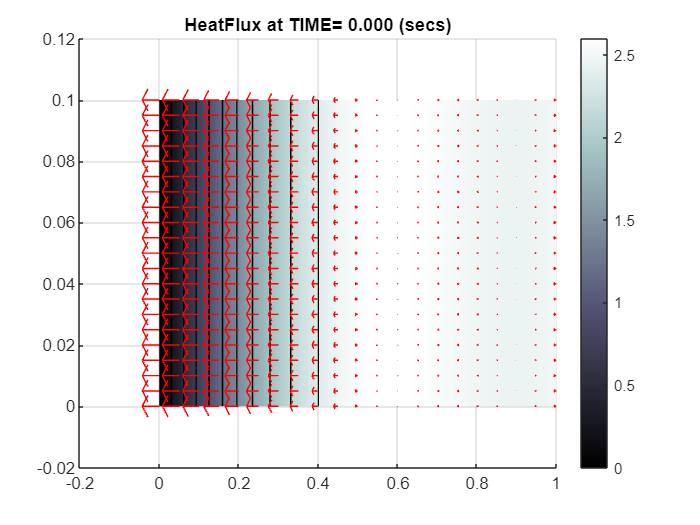

[qx,qy] = evaluateHeatFlux(thermalresults);
    
figure;
    pdeplot(thermalmodel,'XYData',thermalresults.Temperature(:,t_kk), ...
                         'Contour','on',...
                         'FlowData',[qx(:,t_kk),qy(:,t_kk)], ...
                         'ColorMap','bone')
        grid on
        title("HeatFlux at TIME= " + num2str(tlist(t_kk), "%.3f") + " (secs)" )

### Interpolate the Temperature solution at the Y-centerline of the rectangle

my_x_list  = 0:0.001:1;
my_y_list = ones(size(my_x_list))*bh_GEOM.rect_height/2;

Tintrp = interpolateTemperature( thermalresults, ...
                                 my_x_list, my_y_list, ...
                                 1:length(thermalresults.SolutionTimes) );

### And visualize:

-  NOTE:  the slider bar represents "normalised time", i.e.: 

- $\Longrightarrow$` t_norm = 1`  , corresponds to $t=t_{\textrm{MAX}}$

- $\Longrightarrow$` t_norm = 0`  , corresponds to $t=t_{\textrm{MIN}}$

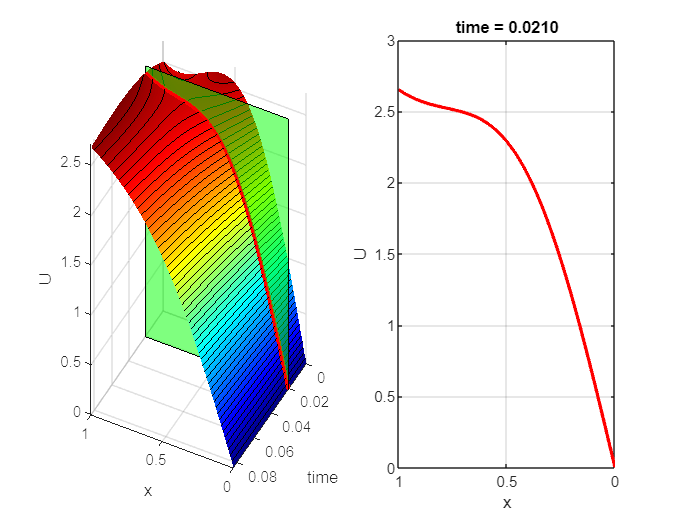

 U      =   Tintrp';
 t_norm = 0.25;
 
 LOC_slice_and_dice_for_pde_tbox(U, my_x_list, thermalresults.SolutionTimes, t_norm)

# Local subfunctions only beyond this point

### Other things:

function [A,B,P] = LOC_get_ABP()
    A       = 2.2;
    B       = 0.7; %2.2; %0.7;
    P       = 3;    
end

**Plot the Initial Condition:**

function LOC_plot_IC(T0, x_range)

  tmp.x = linspace( x_range(1), x_range(2), 500  );
  T = T0(tmp);
  
  figure;
      plot(tmp.x, T, '-b');
          xlabel('Position (m)'); ylabel('Temperature (oK)');
          title("INITIAL temperature distribution");
          grid("on")
end

**Slice and Dice for pdepe results:**

Recall the layout of the U solution

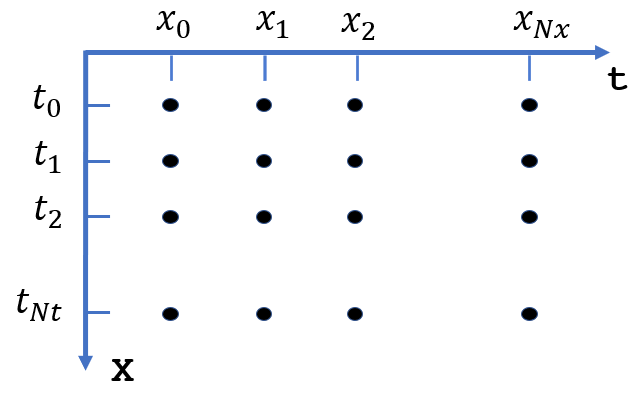

function LOC_slice_and_dice_for_pde_tbox(U, x_list, t_list, t_norm)

    kk_t   = 1 +  round(t_norm*(-1+length(t_list)));

    t_val = t_list(kk_t);   
    U_vec = U(kk_t,:);
    x_vec = x_list;
      
    % set up figure and the 2 axes
    figure;
    hax(1) = subplot(1,2,1);
    hax(2) = subplot(1,2,2);
   
    % plot the U vs X slice
    plot(hax(2), x_vec, U_vec, '-r', 'LineWidth', 2);
        grid(hax(2), 'on');
        xlabel(hax(2),'x'); ylabel(hax(2),'U');
        set(hax(2), 'XDir', 'reverse');
        title("time = " + num2str(t_val, '%.4f') );
    
    % plot the 3D surface
    t = t_list;
    x = x_list;
    hAX = hax(1);
    surf(hAX, x,t, U, 'EdgeColor','none');
        xlabel(hAX,'x');
        ylabel(hAX, 'time');
        zlabel(hAX, 'U');
        %lightangle(75, 70)
        hold(hAX,'on')
    set(hAX, "CLim",[min(U(:)),  max(U(:))]);   
    colormap(jet);
    
    contour3(hAX, x,t, U, 50, '-k')    
    
    % plot the slice plane
    yp = [t_val, t_val, t_val, t_val ];
    xp = [x_vec(1), x_vec(end), x_vec(end), x_vec(1) ];
    zp = [0,0,max(U,[],'all'), max(U,[],'all')];
    patch(hAX, xp,yp,zp, 'g', 'FaceAlpha', 0.5);   
    y_vec = t_val*ones(size(x_vec));
    
    plot3(hAX,x_vec,y_vec,U_vec, '-r', 'LineWidth',3)
    %view(hAX,[36.66 29.04])
    view(hAX,[207.05 23.26])
end